## **Read Data**

data = load('/Users/rogermatos/Documents/Deep Learning/InsectClassification/matlab_dataset/insect_dataset.mat');

all_images = data.all_images;
all_dnas = data.all_dnas;
all_labels = data.all_labels;
train_loc = data.train_loc;
val_seen_loc = data.val_seen_loc;
val_unseen_loc = data.val_unseen_loc;
test_seen_loc = data.test_seen_loc;
test_unseen_loc = data.test_unseen_loc;
species2genus = data.species2genus;
described_species_labels_train = data.described_species_labels_train;
described_species_labels_trainval = data.described_species_labels_trainval;



## **Network**

layers = [
    
    imageInputLayer([658, 5, 1])

    convolution2dLayer(3, 64, Padding='same', NumChannels=1)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([3,1])

    convolution2dLayer(3, 32, Padding='same', NumChannels=64)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([3,1])

    convolution2dLayer(3, 16, Padding='same', NumChannels=32)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([3,1])

    flattenLayer
     
    fullyConnectedLayer(500, 'Name', 'fc_500')
    tanhLayer
     
    fullyConnectedLayer(703)
    softmaxLayer
    classificationLayer

]

layers =   19×1 Layer array with layers:

     1   ''         Image Input             658×5×1 images with 'zerocenter' normalization
     2   ''         2-D Convolution         64 3×3×1 convolutions with stride [1  1] and padding 'same'
     3   ''         Batch Normalization     Batch normalization
     4   ''         ReLU                    ReLU
     5   ''         2-D Max Pooling         3×1 max pooling with stride [1  1] and padding [0  0  0  0]
     6   ''         2-D Convolution         32 3×3×64 convolutions with stride [1  1] and padding 'same'
     7   ''         Batch Normalization     Batch normalization
     8   ''         ReLU                    ReLU
     9   ''         2-D Max Pooling         3×1 max pooling with stride [1  1] and padding [0  0  0  0]
    10   ''         2-D Convolution         16 3×3×32 convolutions with stride [1  1] and padding 'same'
    11   ''         Batch Normalization

## **Prepare data**

numClasses = numel(unique(all_labels));

trainData = all_dnas(train_loc, :, :);
trainData = reshape(trainData, [658, 5, 1, 13039]);

trainLabels = all_labels(train_loc);

valSeenData = all_dnas(val_seen_loc, :, :);
valSeenData = reshape(valSeenData, [658, 5, 1, 3234])

valSeenData = valSeenData(:,:,1,1) =

     1     1     0     0     1
     1     1     0     1     1
     0     1     0     1     1
     1     1     1     1     1
     1     0     0     1     1
     1     1     0     0     0
     1     1     0     1     0
     1     1     0     0     0
     1     0     0     0     0
     1     0     0     1     0
     0     0     0     1     0
     1     1     0     0     0
     1     0     0     0     0
     0     0     0     0     1
     0     1     0     0     1
     1     0     0     0     1
     0     0     1     0     1
     1     0     0     0     1
     1     0     0     1     1
     1     1     1     0     1
     0     1     0     1     1
     1     1     1     1     1
     0     0     0     1     1
     1     0     1     0     1
     0     1     1     0     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
 

valSeenLabels = (all_labels(val_seen_loc));

valUnseenData = all_dnas(val_unseen_loc, :, :);
valUnseenLabels = all_labels(val_unseen_loc);

%combinedValData = cat(1, valSeenData, valUnseenData);
%combinedValLabels = [valSeenLabels, valUnseenLabels];
numerical_train = trainLabels;
numerical_valSeen = valSeenLabels;


trainLabels = categorical(trainLabels);
valSeenLabels = categorical(all_labels(val_seen_loc));

%combinedValLabels = categorical(combinedValLabels);
%%ValidationData = {valSeenData,valSeenLabels},...
size(trainData)

ans =          658           5           1       13039


## Training1

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        0.00% |       6.6461 |          0.0050 |
|       1 |          50 |       00:00:20 |        0.00% |       7.7158 |          0.0050 |
|       1 |         100 |       00:00:40 |        6.25% |       7.9530 |          0.0050 |
|       1 |         150 |       00:01:04 |        3.12% |       7.8011 |          0.0050 |
|       1 |         200 |       00:01:22 |        0.00% |       8.3685 |          0.0050 |
|       1 |         250 |       00:01:36 |        0.00% |       9.2204 |          0.0050 |
|       1 |         300 |  

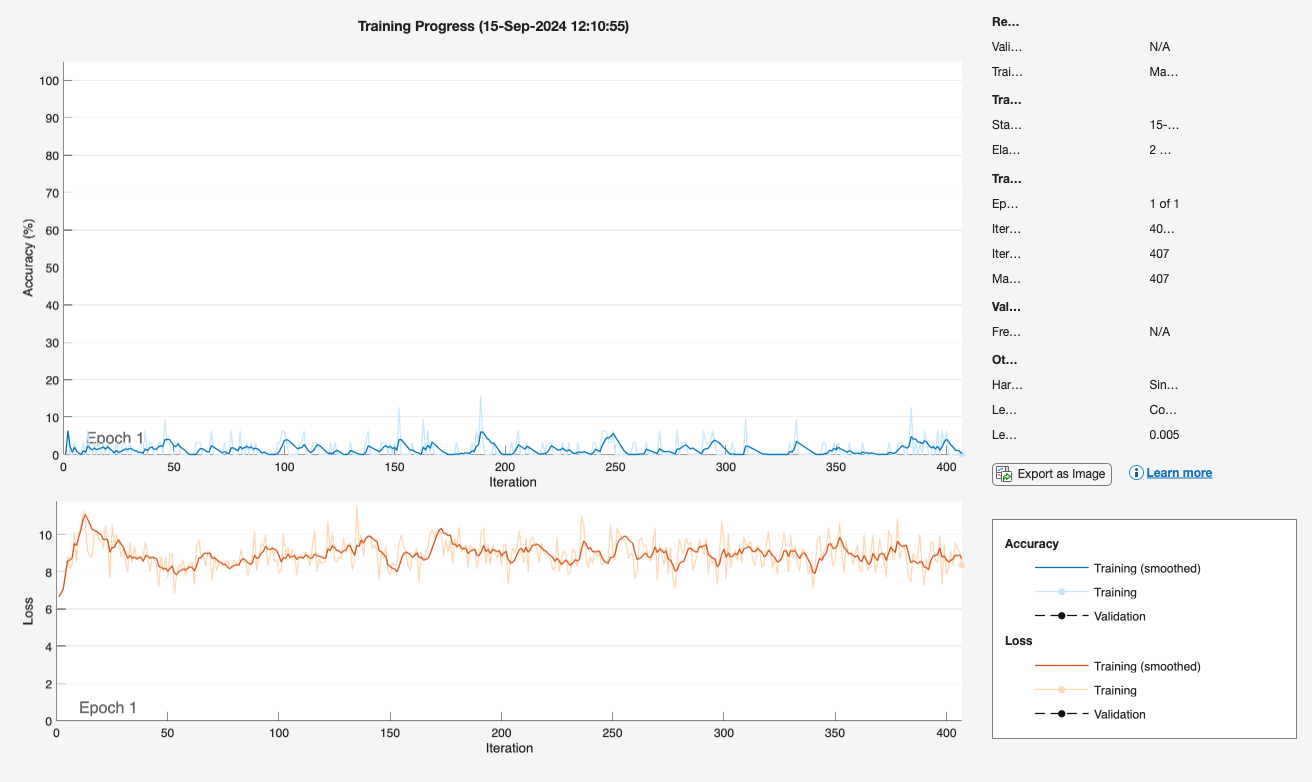

options = trainingOptions("adam", ...
    InitialLearnRate=5e-3, ...
    LearnRateDropFactor=0.5, ... 
    GradientDecayFactor=0.9, ...
    SquaredGradientDecayFactor=0.999,...
    MaxEpochs=1, ...
    MiniBatchSize=32, ...
    Plots="training-progress", ...
    Shuffle= 'every-epoch', ...
    Verbose=true);

net = trainNetwork(trainData, trainLabels, layers, options);

save("/Users/rogermatos/Documents/Deep Learning/InsectClassification/dna_matlab_weights.mat", "net")

all_dna_features_cnn_original = forward(net, trainData, 'fc_500');

save('/Users/rogermatos/Documents/Deep Learning/InsectClassification/matlab_dataset/insect_dataset.mat', 'all_dna_features_cnn_original', '-append');

    0.0043



    0.0088

